## , Preparación del modelo en matemárica simbólica

% Definición de variables y parámetros simbólicos
syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)          % Variables
syms lambda beta_m mu_m theta_m mu_h beta_h theta_h gamma_h     % Parámetros

% Definición del sistema de ecuaciones diferenciales
H=Hs+He+Hi+Hr;
M=Ms+Me+Mi;
ode1 = diff(Ms) == lambda - beta_m*Hi*Ms/H - (mu_m)*Ms;
ode2 = diff(Me) == beta_m*Hi*Ms/H - (theta_m+mu_m)*Me;
ode3 = diff(Mi) == theta_m*Me - mu_m*Mi;
ode4 = diff(Hs) == -beta_h*Mi*Hs/M + (He+Hi+Hr)*mu_h;
ode5 = diff(He) == beta_h*Mi*Hs/M - (theta_h+mu_h)*He;
ode6 = diff(Hi) == theta_h*He - (gamma_h+mu_h)*Hi;
ode7 = diff(Hr) == gamma_h*Hi - mu_h*Hr;
ode8 = diff(Hit) == theta_h*He;
odes=[ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8]   % Arreglo con el sistema

$$odes(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{Ms}\left(t\right)=\lambda -\mu_{m}\,\mathrm{Ms}\left(t\right)-\sigma_{1}\\ \frac{\partial }{\partial t}\mathrm{Me}\left(t\right)=\sigma_{1}-\mathrm{Me}\left(t\right)\,\left(\theta_{m}+\mu_{m}\right)\\ \frac{\partial }{\partial t}\mathrm{Mi}\left(t\right)=\theta_{m}\,\mathrm{Me}\left(t\right)-\mu_{m}\,\mathrm{Mi}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{Hs}\left(t\right)=\mu_{h}\,\left(\mathrm{He}\left(t\right)+\mathrm{Hi}\left(t\right)+\mathrm{Hr}\left(t\right)\right)-\sigma_{2}\\ \frac{\partial }{\partial t}\mathrm{He}\left(t\right)=\sigma_{2}-\mathrm{He}\left(t\right)\,\left(\theta_{h}+\mu_{h}\right)\\ \frac{\partial }{\partial t}\mathrm{Hi}\left(t\right)=\theta_{h}\,\mathrm{He}\left(t\right)-\mathrm{Hi}\left(t\right)\,\left(\gamma_{h}+\mu_{h}\right)\\ \frac{\partial }{\partial t}\mathrm{Hr}\left(t\right)=\gamma_{h}\,\mathrm{Hi}\left(t\right)-\mu_{h}\,\mathrm{Hr}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{Hit}\left(t\right)=\theta_{h}\,\mathrm{He}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\beta_{m}\,\mathrm{Hi}\left(t\right)\,\mathrm{Ms}\left(t\right)}{\mathrm{He}\left(t\right)+\mathrm{Hi}\left(t\right)+\mathrm{Hr}\left(t\right)+\mathrm{Hs}\left(t\right)}\\ \sigma_{2}=\frac{\beta_{h}\,\mathrm{Hs}\left(t\right)\,\mathrm{Mi}\left(t\right)}{\mathrm{Me}\left(t\right)+\mathrm{Mi}\left(t\right)+\mathrm{Ms}\left(t\right)} \end{array}$$

% Orden para las variables de estado y tabla T del sistema
vars=[Hit Hi Me Hr Hs He Ms Mi];
domain = [0 62]; % Dominio del tiempo (intervalo de solución, i.e., el tiempo)
modelName = '7m';
opts = odeset('NonNegative',1:8);
load data/Range7.mat % Intervalos de las variables, definen el espacio de estado de los factores

% Generamos la tabla del sistema con el rango default (Inf, Sup)
[T,~]=gsua_dpmat(odes,vars,domain,modelName,'output',1,'opt',opts,'Range',Range); % El parámetro omitido es del solver ode45 que usa el toolbox

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T % Visualizar la tabla del sistema

T = 13×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    He0               18            72            45
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    beta_h             0             4             2
    beta_m             0             4             2
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    mu_m            0.16           0.2          0.18
    theta_h          0.

T.Properties.CustomProperties % Se observa que el solver únicamente tiene la salida 1

ans = CustomProperties with properties:

     Solver: @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)
    NumVars: 6
     output: 1
     Domain: [0 62]
    rMethod: 'range'
       Kind: 3
      Fixed: []
       Vars: {'Hit'  'Hi'  'Me'  'Hr'  'Hs'  'He'  'Ms'  'Mi'}
      Sname: []
    creator: [1×1 struct]


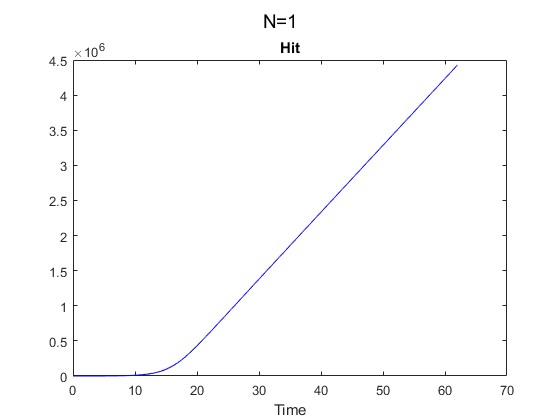

ans = 	1.0e+06 *

    0.0000    0.0001    0.0001    0.0003    0.0005    0.0008    0.0014    0.0023    0.0038    0.0063    0.0102    0.0164    0.0261    0.0410    0.0631    0.0949    0.1384    0.1950    0.2641    0.3435    0.4302    0.5213    0.6149    0.7098    0.8052    0.9009    0.9967    1.0925    1.1883    1.2840    1.3797    1.4753    1.5709    1.6664    1.7618    1.8572    1.9526    2.0479    2.1432    2.2384    2.3337    2.4289    2.5242    2.6194    2.7146    2.8098    2.9049    3.0001    3.0953    3.1905


gsua_eval(T.Nominal,T) % Se evalúa la respuesta del sistema ante los valores nominales

## Análisis de sensibilidad

% Matriz de diseño: forma de explorar el espacio de los parámetros
N = 10000; % Número de muestras o puntos de exploración
M = gsua_dmatrix(T,N,'Show','off','Method','Sobol');

T=gsua_sa(M,T,'parallel',false); % Análisis de sensibilidad

Progress: 7%
Estimated processing time (h:m:s): 0:14:52
Remaining time (h:m:s): 0:13:53
Elapsed time (h:m:s): 0:0:59
Estimated stop time (h:m:s): 22:49:21
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:14:10
Remaining time (h:m:s): 0:12:17
Elapsed time (h:m:s): 0:1:53
Estimated stop time (h:m:s): 22:48:39
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:14:12
Remaining time (h:m:s): 0:11:22
Elapsed time (h:m:s): 0:2:50
Estimated stop time (h:m:s): 22:48:41
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:13:56
Remaining time (h:m:s): 0:10:13
Elapsed time (h:m:s): 0:3:43
Estimated stop time (h:m:s): 22:48:25
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:14:5
Remaining time (h:m:s): 0:9:23
Elapsed time (h:m:s): 0:4:41
Estimated stop time (h:m:s): 22:48:34
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:14:11
Remaining time (h:m:s

save('Results_10000.mat') % Se guardan resultados

T % Se observan los índicies de sensibilidad (Si), de sensibilidad total (STi) y los vectoriales (STi_vec, Si_vec)

T = 13×6 table
                        Range              Nominal          Si            STi          STi_vec          Si_vec    
               _______________________    __________    ___________    _________    _____________    _____________

    Me0                0           100            50    -1.2807e-05    0.0052814    [1×63 double]    [1×63 double]
    Hr0            81405    1.5881e+05    1.2011e+05      0.0033726     0.086206    [1×63 double]    [1×63 double]
    Hs0        2.444e+05    3.2173e+05    2.8307e+05      0.0016863     0.079265    [1×63 double]    [1×63 double]
    He0               18            72            45    -0.00018353     0.010099    [1×63 double]    [1×63 double]
    Ms0    

Tomado del [user guide](https://drojasd.github.io/GSUA-CSB/gsua_userguide) del toolbox.

De acuerdo con Saltelli y el Método de Distancia, una buena elección de $N$ ocurre cuando no hay valores negativos presentes en $\mathrm{Si}$. En este caso hay valores negativos, por lo que es necesario considerar un $N$ mayor al elegido.

El índice más relevante para evaluar la relevancia de los parámetros es $\mathrm{STi}$. Sin embargo, es necesario considerar que: $\Sigma \mathrm{STi}$ siempre es $\ge 1$, mientras que $\Sigma \mathrm{Si}$ siempre es $\le 1$. Si una de las sumatorias es igual a 1, la otra tiene que ser 1 también, y por lo tanto, el modelo es puramente aditivo.

Una regla (consejo) general es realizar un Análisis de Sensibilidad (AS) global del modelo cuando la interacción entre factores es desconocida. Si $\Sigma \;\mathrm{Si}\ge 0\ldotp 65$, se puede concluir que el modelo tiene interacciones débiles entre los factores y las interacciones son despreciables. Por lo tanto, para los análisis posteriores, sería mejor realizar AS local o métodos analíticos de AS.

Si la suma de Sti se aproxima lo suficientemente a 1 (<=0.7 en la literatura), quiere decir que el comportamiento no lineal del sistema es muy reducido.

Si la suma de Si es pequeña, quiere decir que no se tiene confianza en los resultados, que el comportamiento del sistema es no lineal, y que debe explorarse a través de técnicas globales (que las conclusiones que provienen de técnicas locales son incorrectas para este espacio de los factores).

sum(T.STi), sum(T.Si)

ans = 2.1565

ans = 0.5043

En este caso la suma $\Sigma \mathrm{STi}$ no se aproxima lo suficientemente a 1, lo que quiere decir que hay interacciones considerablemente fuertes (hay comportamiento no lineal significativo).

En este caso $\Sigma \mathrm{Si}<0\ldotp 65$, entonces se concluye que el modelo tiene interacciones fuertes entre los factores y dichas interacciones son significativas. Por lo tanto, sería mejor realizar AS global para análisis posteriores.

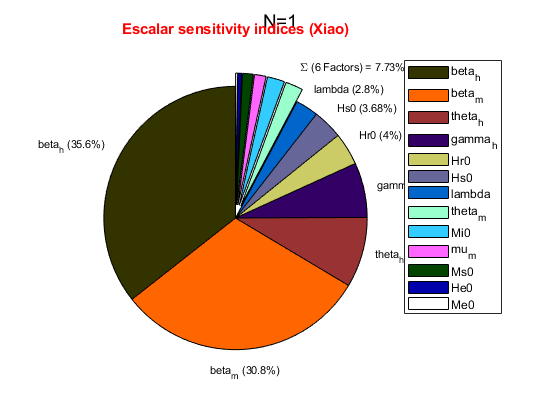

gsua_plot('Pie',T,T.STi);

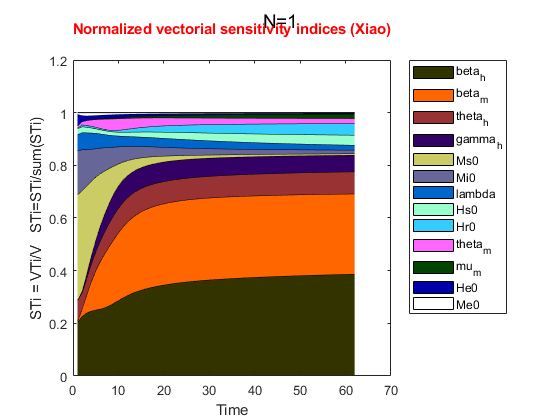

gsua_plot('TotalSensitivityArea',T,T.STi_vec,0:domain(2));

Esta gráfica muestra los índices de sensibilidad totales para cada instante de tiempo. En un instante de tiempo, es posible realizar un análisis de sensibilidad (análisis transversal) para los valores de los índices en ese instante (básicamente crear una torta como la anterior en cada instante de tiempo). **Esta gráfica es valiosa, pues me dice qué parámetro es más influyente y en qué momento. **

En nuestro caso puede ser relevante al analizar una salida específica y buscar un mejor lugar con un mejor ajuste, se podría observar qué parámetro es el que influye más en el ajuste de esa región.